% Output tiff images from matrix for visualization written by NY

clear all;
close all;
clc;

Initial = 'NY';
Animal = 'tlx35'; 
Date = '221118';
Block = 1;
Key = 'min';
working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\';

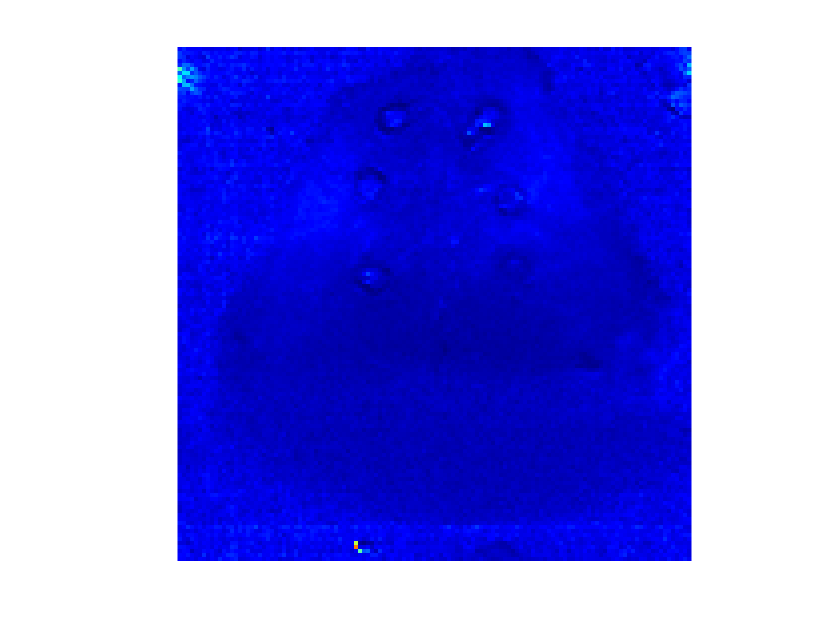

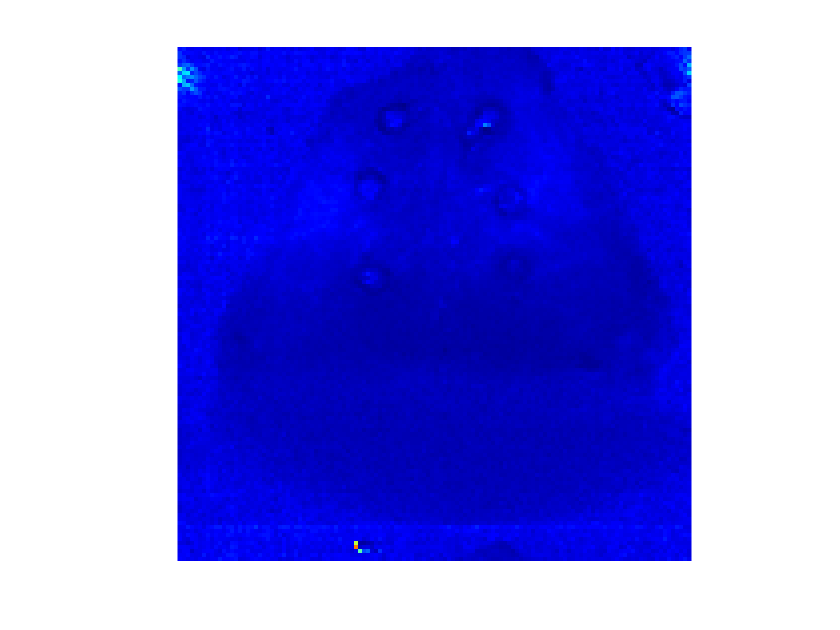

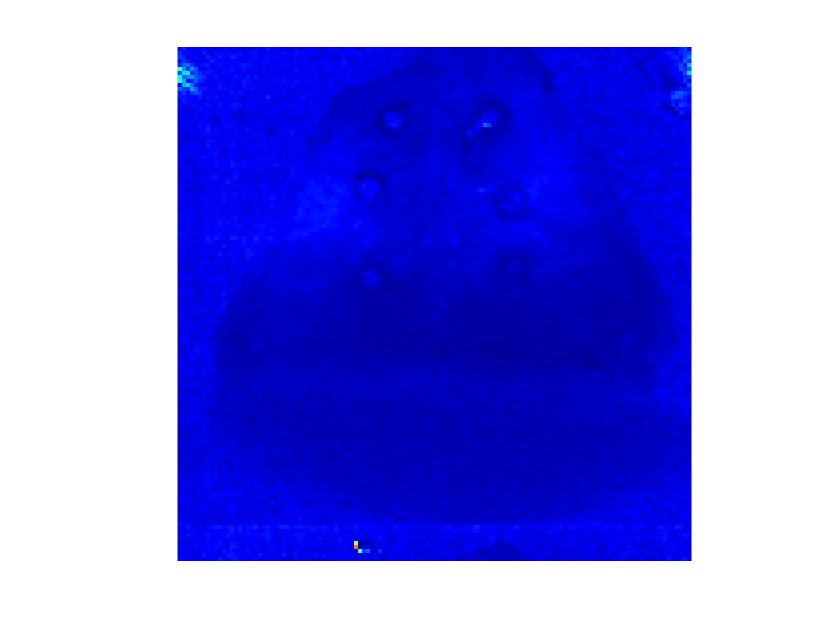

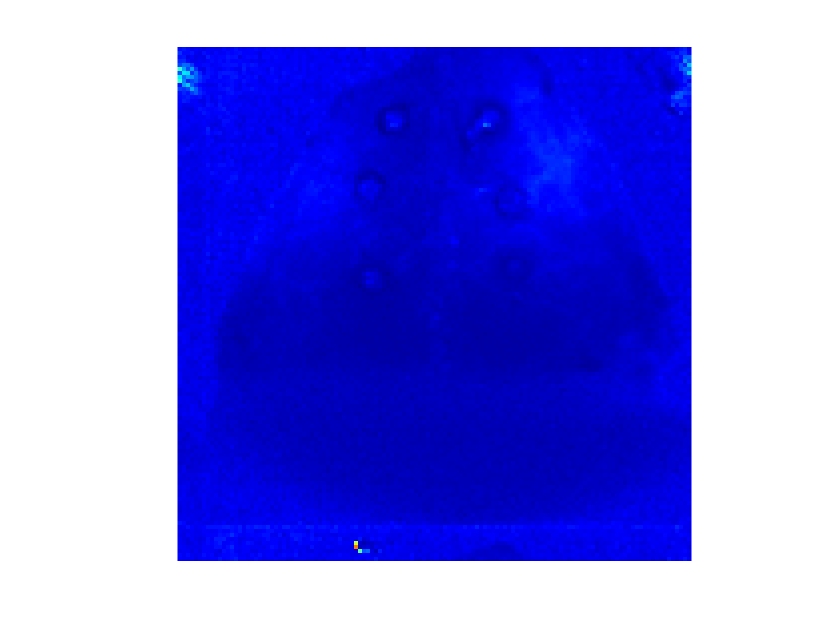

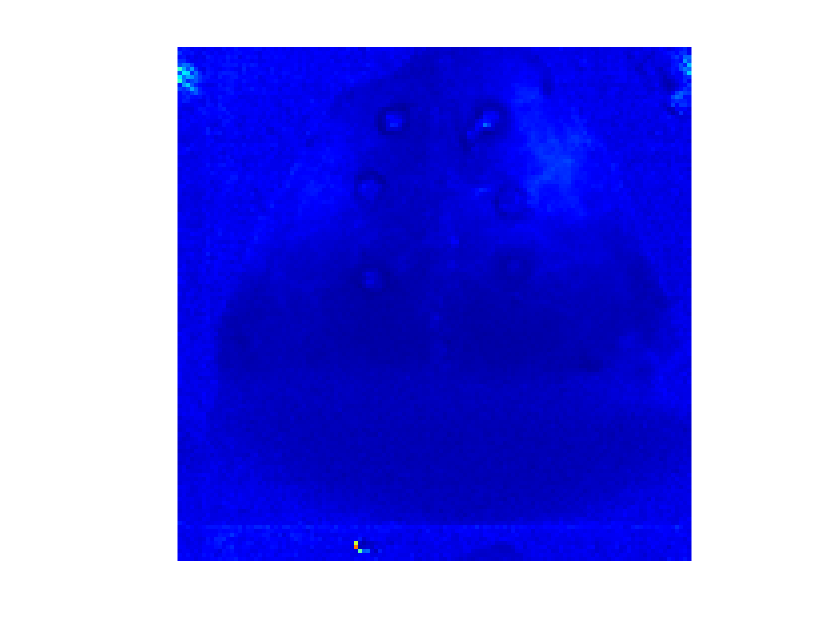

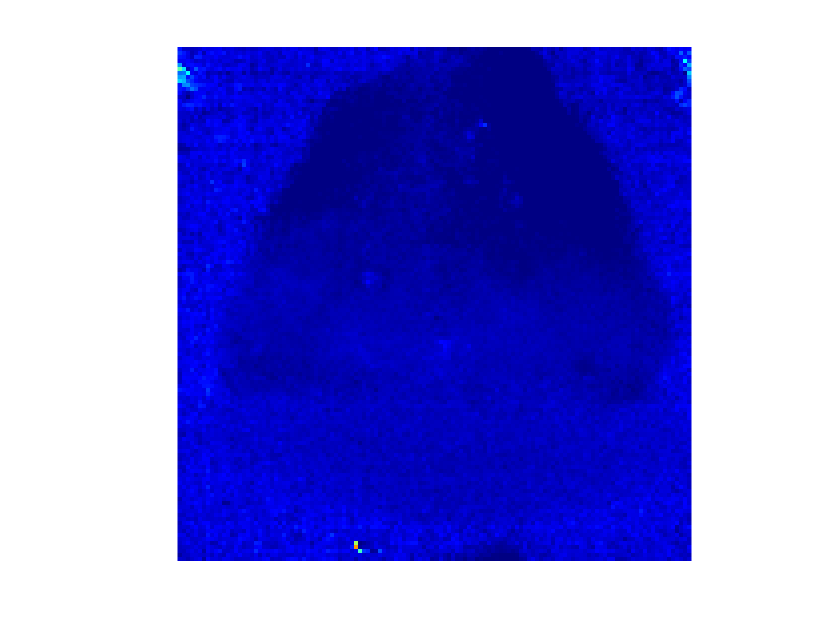

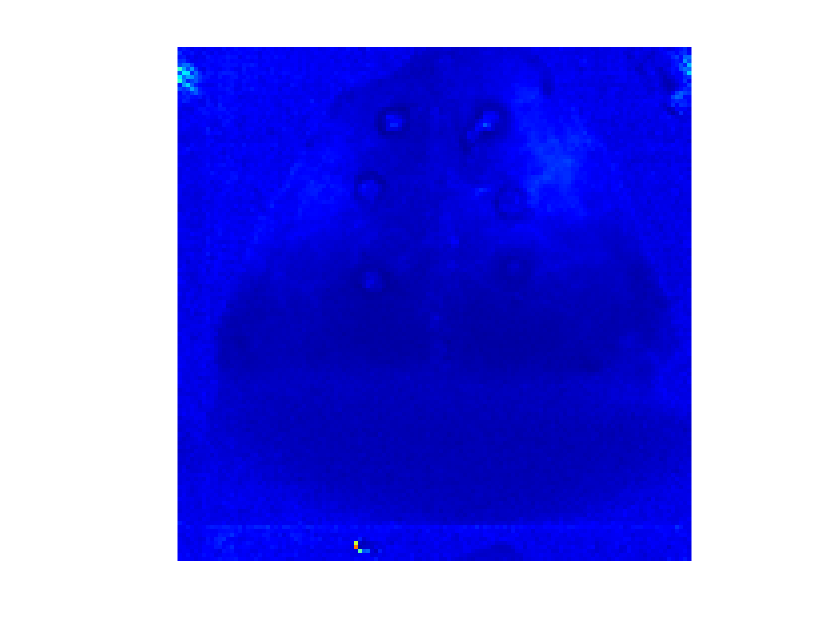

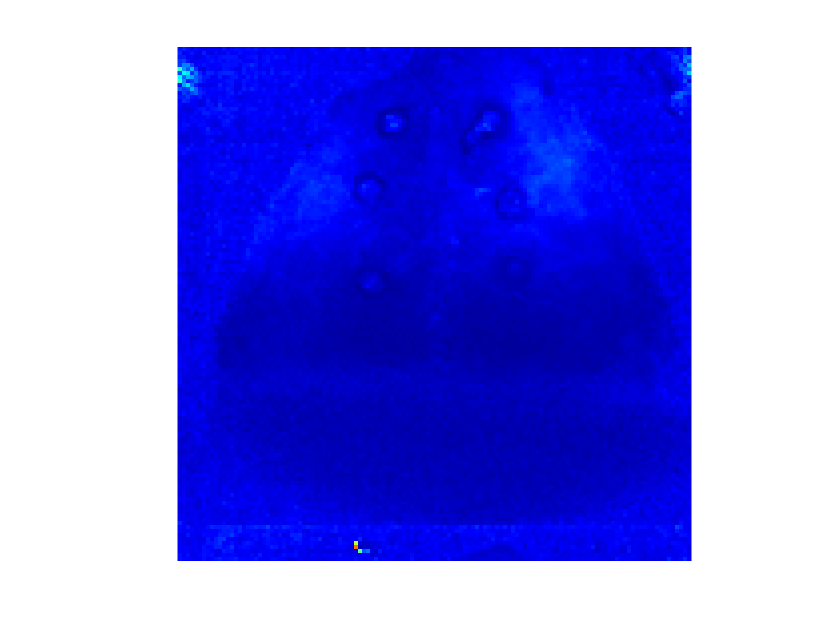

% for visualizing images after df/f
cd ([working_directory Date filesep Initial '_' Animal filesep]);
load([Initial '_' Date '_' Animal '_df_f_all'],'df_f_all','-mat');
mkdir('df_f_out');
for i = 1:size(df_f_all{Block},2)
    figure;
    set(gcf,'color','w');
    clims = [0 0.8]; % [-3 10];
    image = df_f_all{Block}(:,i);
    imagesc(reshape(image,[128 128]),clims);
    colormap jet;
    axis square;
    axis off;
    filename = ['df_f_out' filesep Initial '_' Date '_' Animal '_df_f_', num2str(i), '.tif'];
    saveas(gcf,filename);
end
close all

% y_all = df_f_all{2}
% idx = zeros([1 2000])
% for i = 1:2000
%     idx(i) = 128*53 + 90 + 128 * 128 * (i-1)
% end
% plot(y_all(idx))

% for i = 1:2000
% colormap jet;
% y_re = reshape(y_all(1+128*128*(i-1):128*128*i), [128,128])
% img = heatmap(y_re)
% % saveas(img, 'df_f_out' filesep i '.tif')
% filename = ['df_f_out' filesep 'test', num2str(i), '.tif']
% colormap jet;
% saveas(img, filename)
% end